clc, clear;

# Least Squares

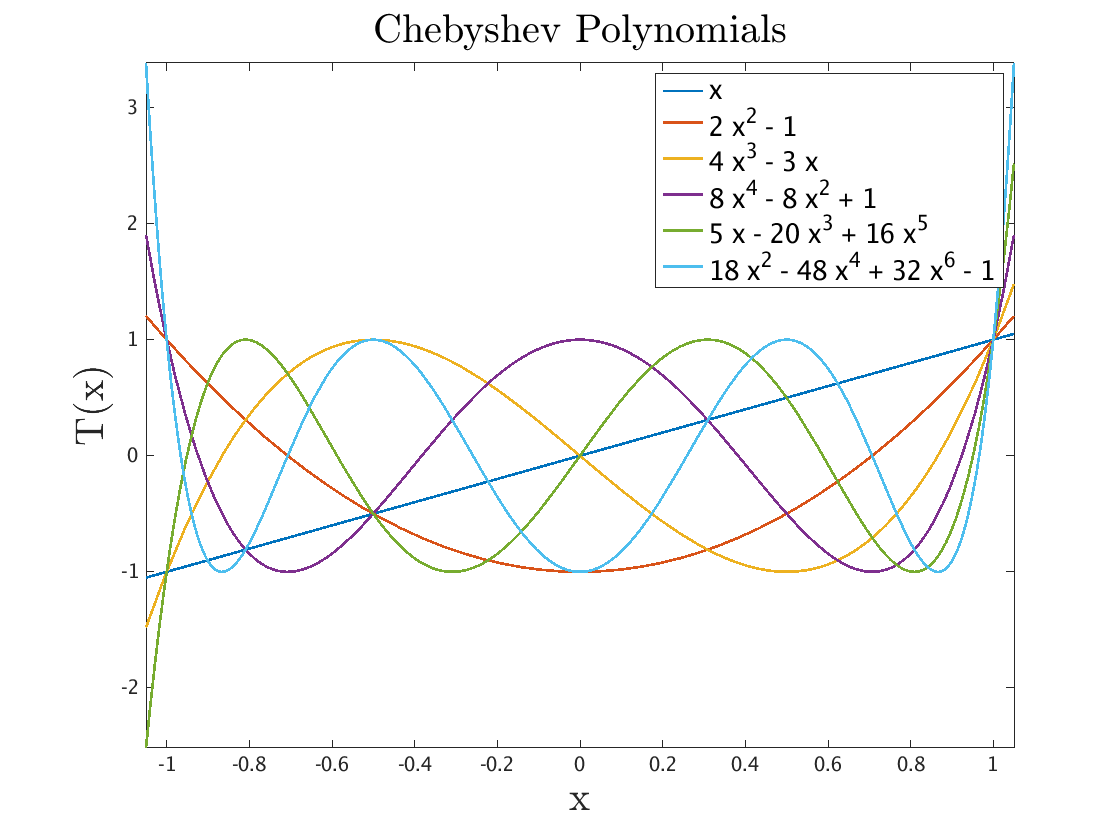

syms x 
% Used 1:6 instead of 1:10 for plot readability 
figure;
fplot(chebyshevT((1:6), x), [-1.05, 1.05], 'LineWidth', 2) 
legend('FontSize', 20)
title('Chebyshev Polynomials', 'Interpreter','latex','FontSize', 30)
ylabel('T(x)','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

f = @(x) 1/(10*x^2+1);

d = zeros(1,50);
s = linspace(-1,1,200);

fn = zeros(1,200);
for i = 1: 200
    fn(1,i) = f(s(i));
end

for n = 1:50
    an = approxCheby(f, 2*n);
    yn = evalCheb(an, s);
    
    d(1,n) = max(abs(yn-fn));
end

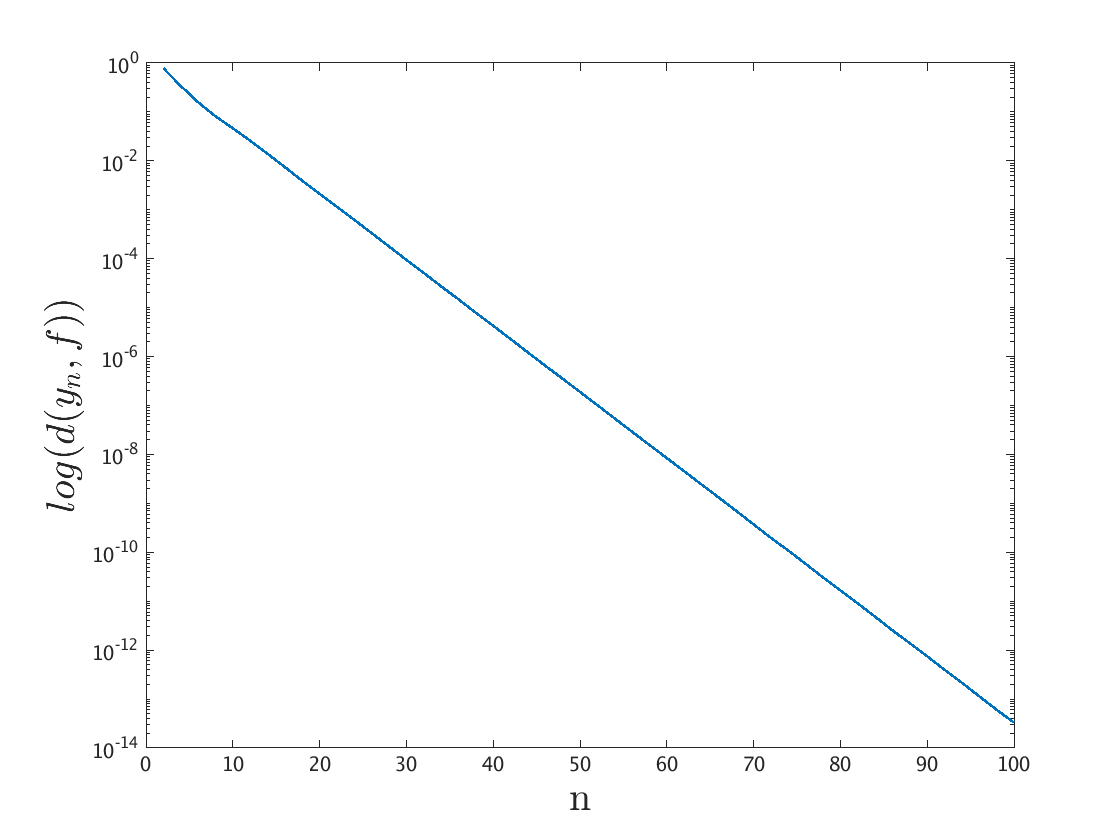

figure
semilogy([2:2:100], d, 'LineWidth', 2)
ylabel('$log(d(y_{n},f))$','Interpreter','latex', 'FontSize', 30)
xlabel('n', 'Interpreter','latex','FontSize', 30)

# Interopolation

syms f_1(x)
syms f_2(x)
f_1(x) = x^10-1;
f_2(x) = 1/(10*x^2+1);

## Equidistant Points

% Interpolation using equidistant points
C_1 = zeros(50,100);
C_2 = zeros(50,100);
kappa_1 = [];
kappa_2 = [];
for n = 2:2:100
    points = linspace(-1,1,n);
    [C_1(n/2, 1:n), kappa_1_temp] = interpolate(points, f_1);
    [C_2(n/2, 1:n), kappa_2_temp] = interpolate(points, f_2);

    kappa_1 = [kappa_1; kappa_1_temp];
    kappa_2 = [kappa_2; kappa_2_temp];
end

% Evaluation of the interpolation using equidistant points
V_1 = [];
V_2 = [];
for n=1:50
    points = linspace(-1,1,n*2);
    V_1_row = zeros(1,100);
    V_1_row(:,1:2*n) = evalCheb(C_1(n,1:2*n), points);
    V_1 = [V_1; V_1_row];

    V_2_row = zeros(1,100);
    V_2_row(:,1:2*n) = evalCheb(C_2(n,1:2*n), points);
    V_2 = [V_2; V_2_row];
end

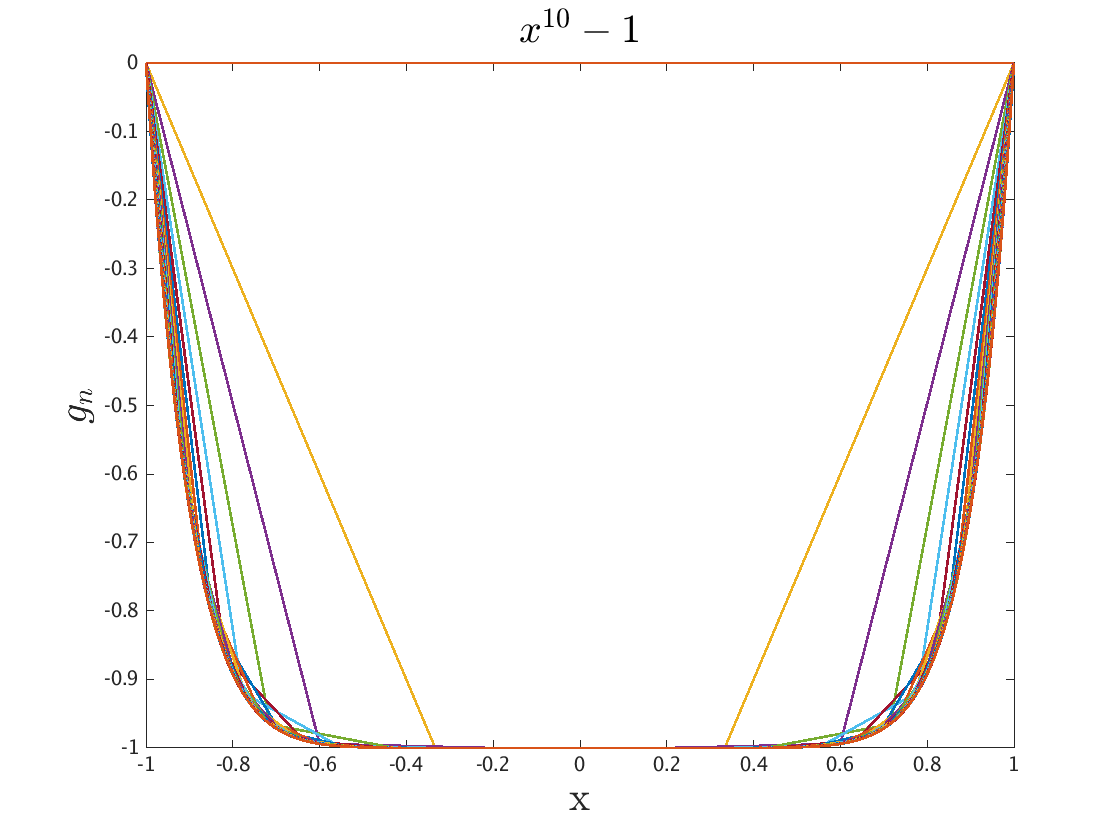

figure(f1);
fplot(f_1, [-1,1], 'DisplayName', 'original', 'LineWidth', 2)
hold on
for k = 1:50
    x = linspace(-1,1,k*2);
    y = V_1(k,1:2*k);
    plot(x,y, 'LineWidth', 2)
end
hold off
title('$x^{10}-1$','Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

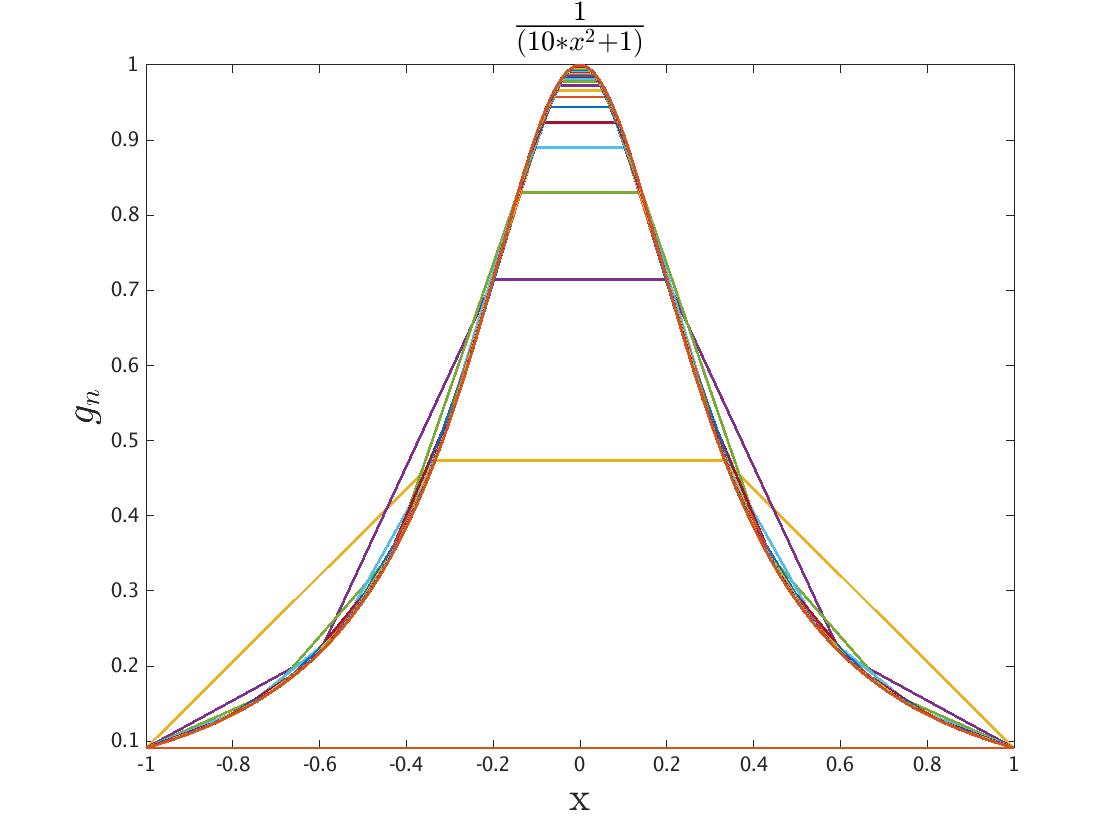



figure(f2);
fplot(f_2, [-1,1], 'DisplayName', 'original', 'LineWidth', 2)
hold on
for k = 1:50
    x = linspace(-1,1,k*2);
    y = V_2(k,1:2*k);
    plot(x,y, 'LineWidth', 2)
end
hold off
title('$\frac{1}{(10*x^2+1)}$', 'Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

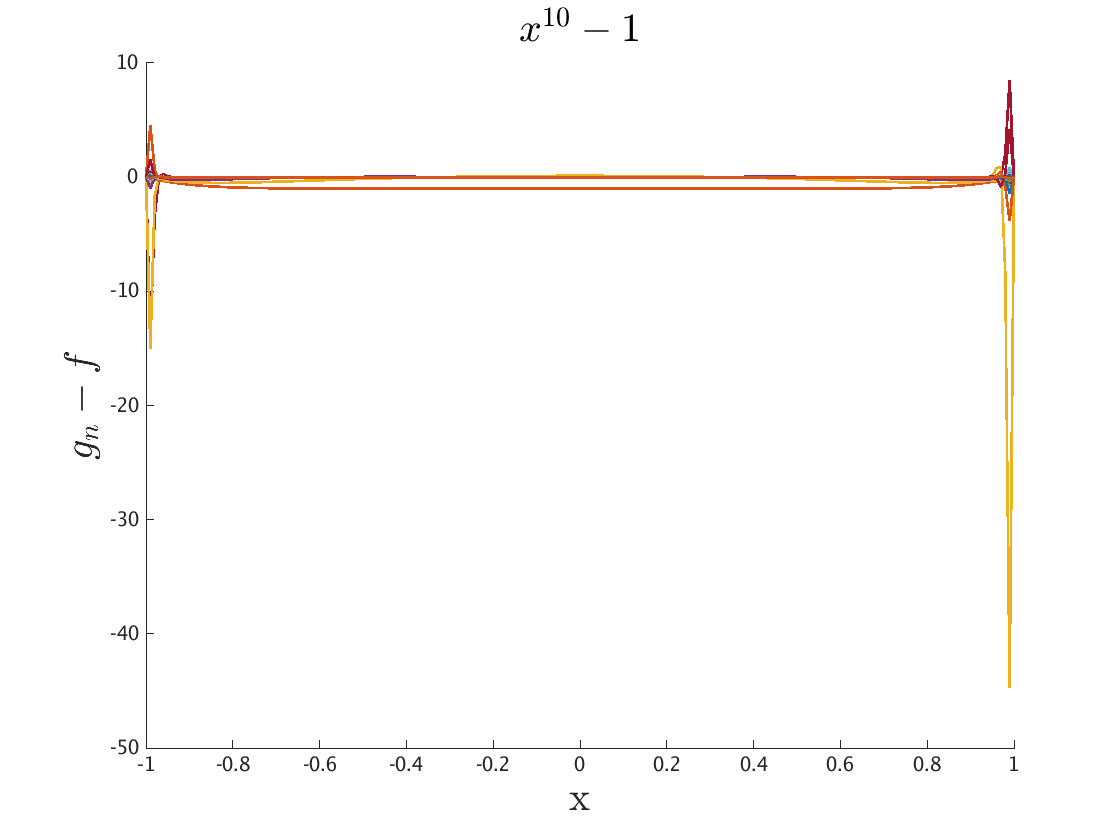

max_error_1 = [];
figure(f3)
for k=1:50
    x = linspace(-1,1, 200);
    f = double(f_1(x));
    y = evalCheb(C_1(k,1:2*k), x);
    
    error_1 = f-y;
    max_error_1 = [max_error_1, abs(max(error_1))];
    
    hold on
    plot(x,error_1, 'LineWidth', 2)
end
hold off
title('$x^{10}-1$','Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}-f$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

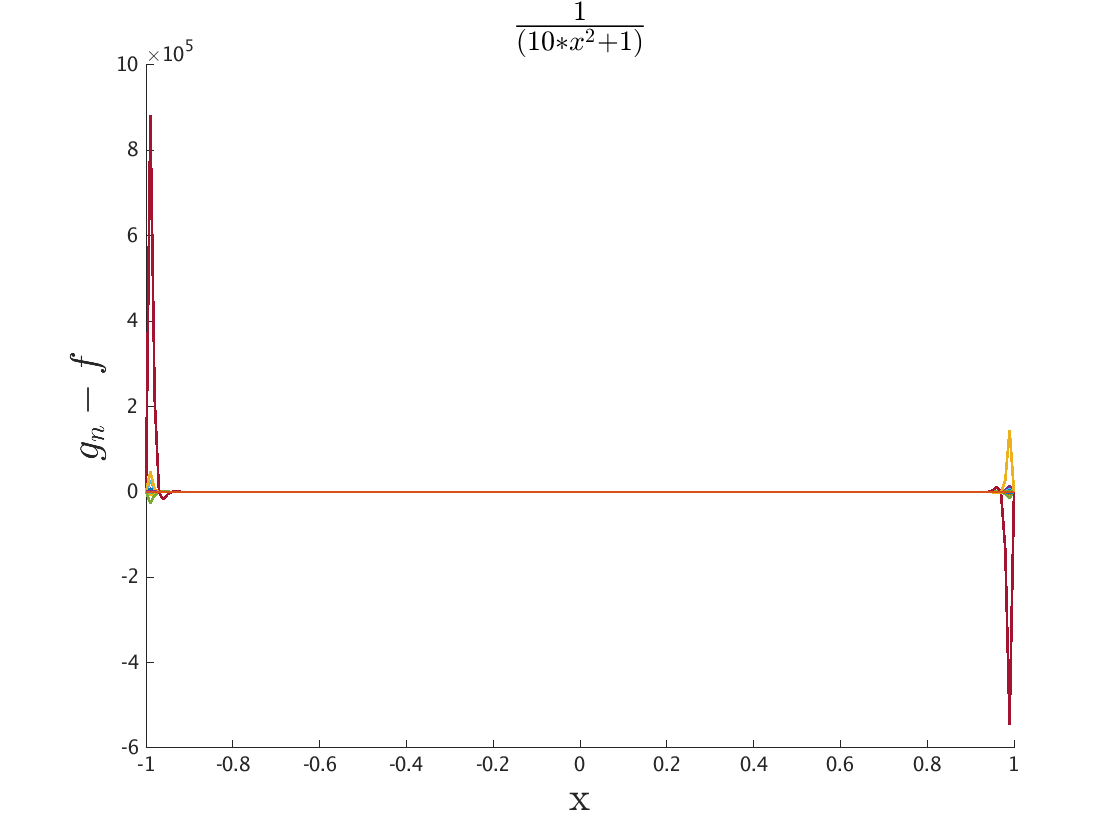

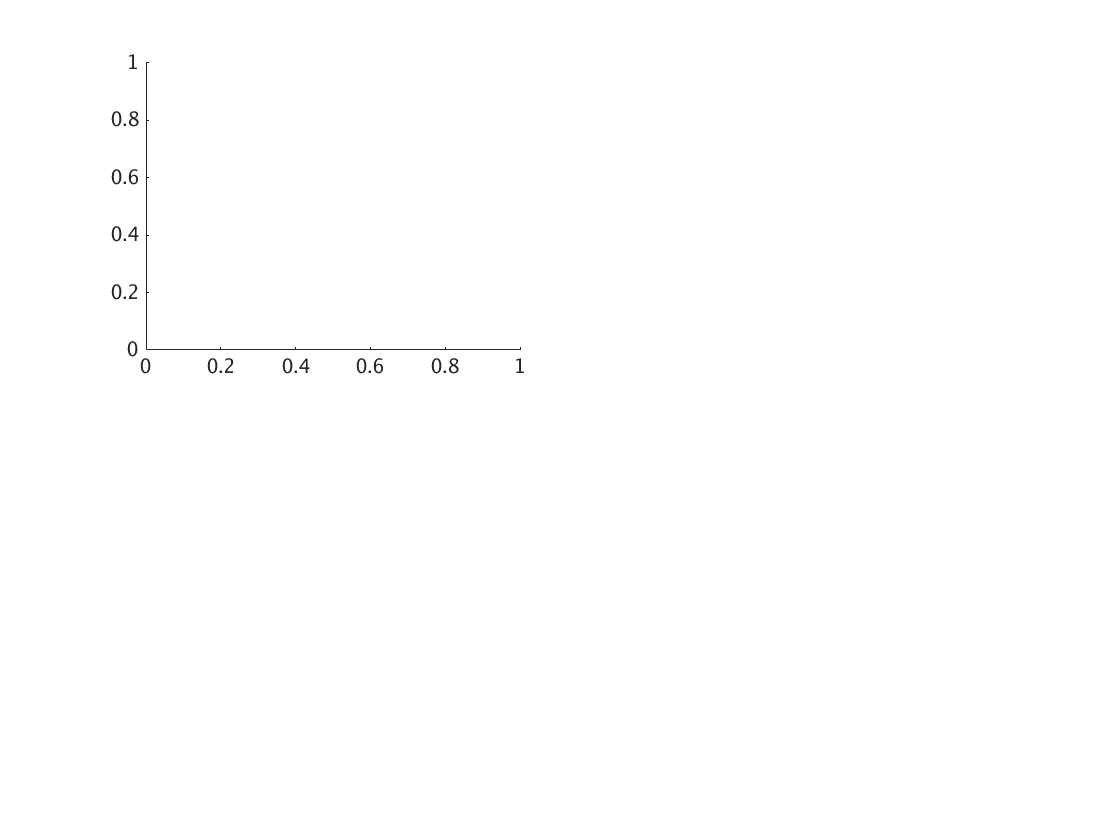

Error using plot
Not enough input arguments.


max_error_2 = [];
figure(f4)
for k=1:50
    x = linspace(-1,1, 200);
    f = double(f_2(x));
    y = evalCheb(C_2(k,1:2*k), x);
    
    error_2 = f-y;
    max_error_2 = [max_error_2, abs(max(error_2))];
    
    hold on
    plot(x,error_2, 'LineWidth', 2)
end
hold off
title('$\frac{1}{(10*x^2+1)}$', 'Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}-f$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

## Chebyshev zeros

% Roots of the cheby polynomial for k=2:2:100
Z = []; 
for k=[2:2:100]
    row = zeros(1, 100);
    for l=1:k
        row(l) = cos(pi*(2*l-1)/(2*k));
    end
    Z = [Z; row];
end

% Interpolation using the chebyshev zeros 

C_3 = [];
C_4 = [];
kappa_3 = [];
kappa_4 = [];
for k=[1:50]
    C_3_row = zeros(1,100);
    [C_3_row(:,1:2*k), kappa_3_temp] = interpolate(Z(k,1:2*k), f_1);
    C_3 = [C_3; C_3_row];

    C_4_row = zeros(1,100);
    [C_4_row(:,1:2*k), kappa_4_temp] = interpolate(Z(k,1:2*k), f_2);
    C_4 = [C_4; C_4_row];

    kappa_3 = [kappa_3; kappa_3_temp];
    kappa_4 = [kappa_4; kappa_4_temp];
end

% Evaluation of the interpolation using the chebyshev zeros
V_3 = [];
V_4 = [];
for n=1:size(Z,1)
    V_3_row = zeros(1,100);
    V_3_row(:,1:2*n) = evalCheb(C_3(n,1:2*n), Z(n,1:2*n));
    V_3 = [V_3; V_3_row];

    V_4_row = zeros(1,100);
    V_4_row(:,1:2*n) = evalCheb(C_4(n,1:2*n), Z(n,1:2*n));
    V_4 = [V_4; V_4_row];
end

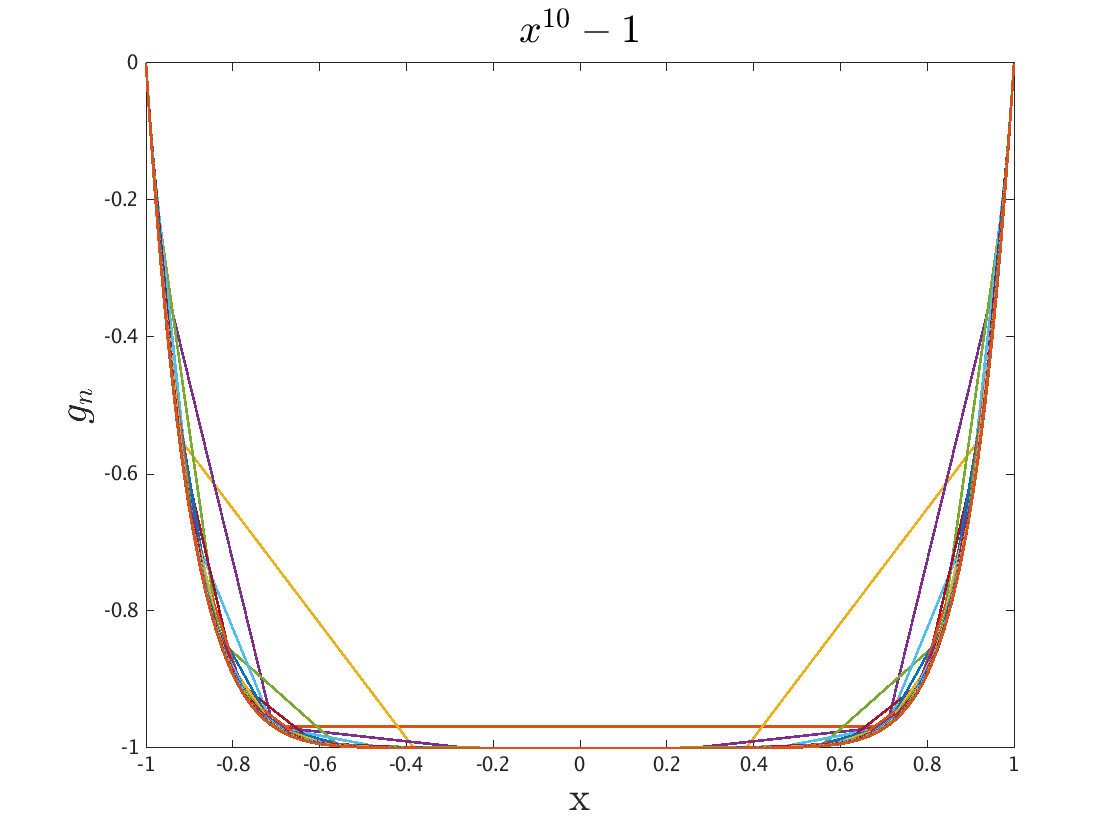

figure;
fplot(f_1, [-1,1], 'DisplayName', 'original', 'LineWidth', 2)
hold on
for k = 1:size(Z,1)
    x = Z(k,1:2*k);
    y = V_3(k,1:2*k);
    plot(x,y, 'LineWidth', 2)
end
hold off
title('$x^{10}-1$','Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

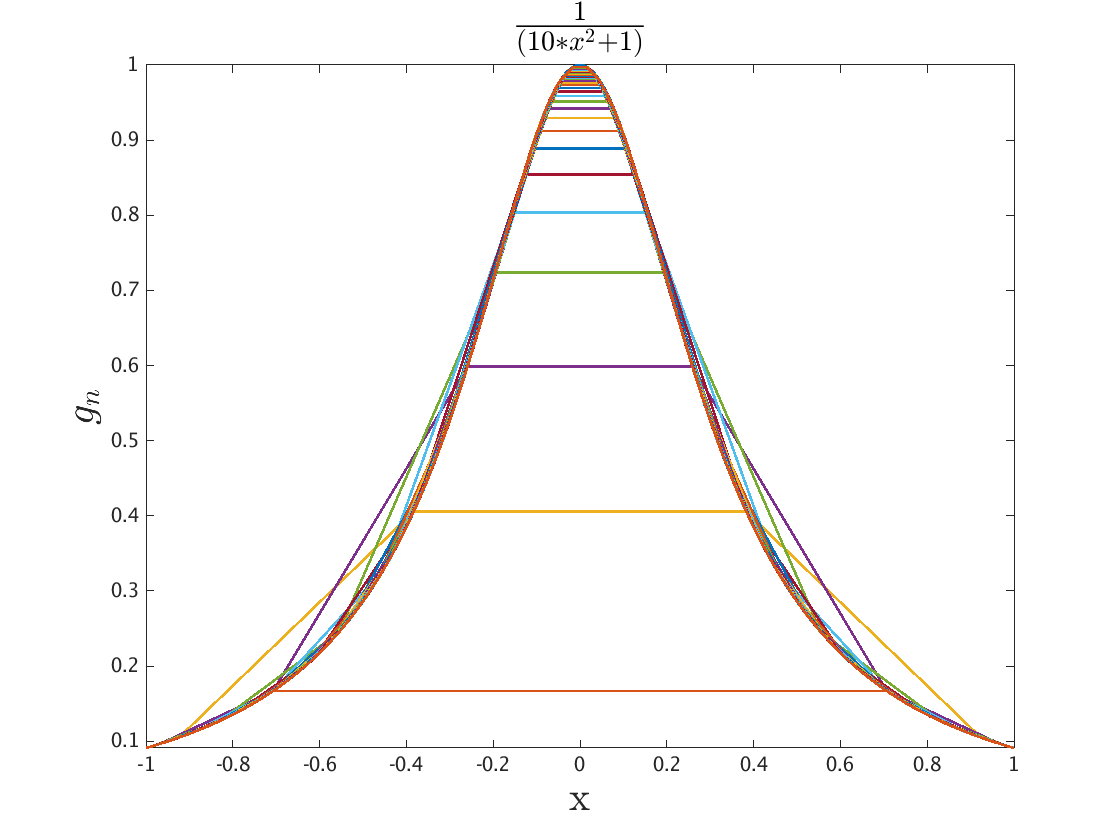


figure;
fplot(f_2, [-1,1], 'DisplayName', 'original', 'LineWidth', 2)
hold on
for k = 1:size(Z,1)
    x = Z(k,1:2*k);
    y = V_4(k,1:2*k);
    plot(x,y, 'LineWidth', 2)
end
hold off
title('$\frac{1}{(10*x^2+1)}$', 'Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

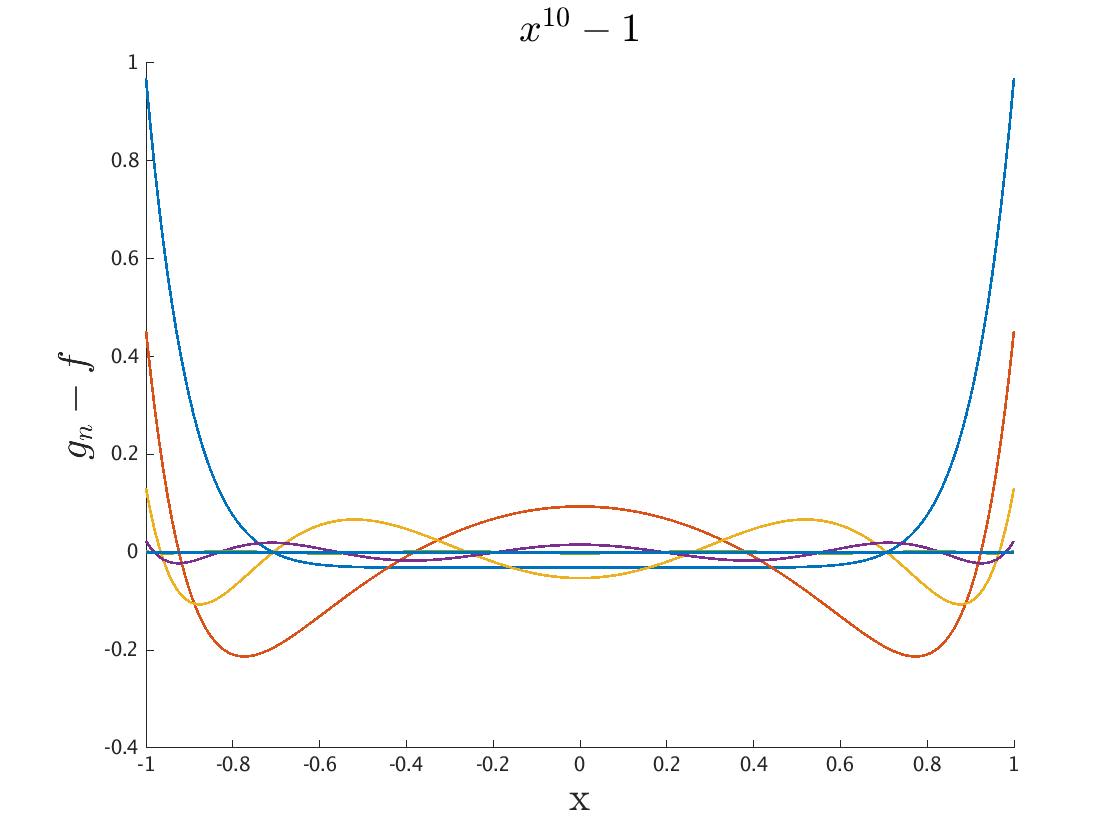

max_error_3 = [];
figure
for k=1:50
    x = linspace(-1,1, 200);
    f = double(f_1(x));
    y = evalCheb(C_3(k,1:2*k), x);
    
    error_3 = f-y;
    max_error_3 = [max_error_3, abs(max(error_3))];
    
    hold on
    plot(x,error_3, 'LineWidth', 2)
end
hold off
title('$x^{10}-1$','Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}-f$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

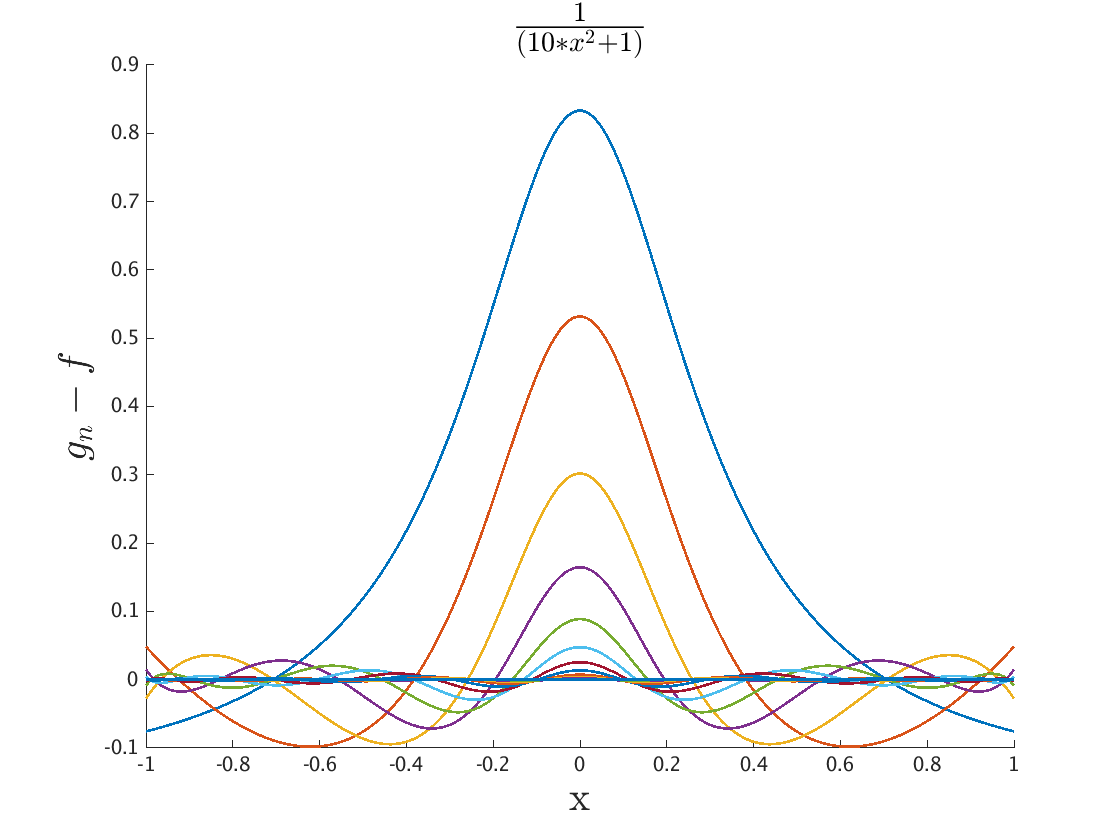



max_error_4 = [];
figure
for k=1:50
    x = linspace(-1,1, 200);
    f = double(f_2(x));
    y = evalCheb(C_4(k,1:2*k), x);
    
    error_4 = f-y;
    max_error_4 = [max_error_4, abs(max(error_4))];
    
    hold on
    plot(x,error_4, 'LineWidth', 2)
end
hold off
title('$\frac{1}{(10*x^2+1)}$', 'Interpreter','latex', 'FontSize', 30)
ylabel('$g_{n}-f$','Interpreter','latex', 'FontSize', 30)
xlabel('x', 'Interpreter','latex','FontSize', 30)

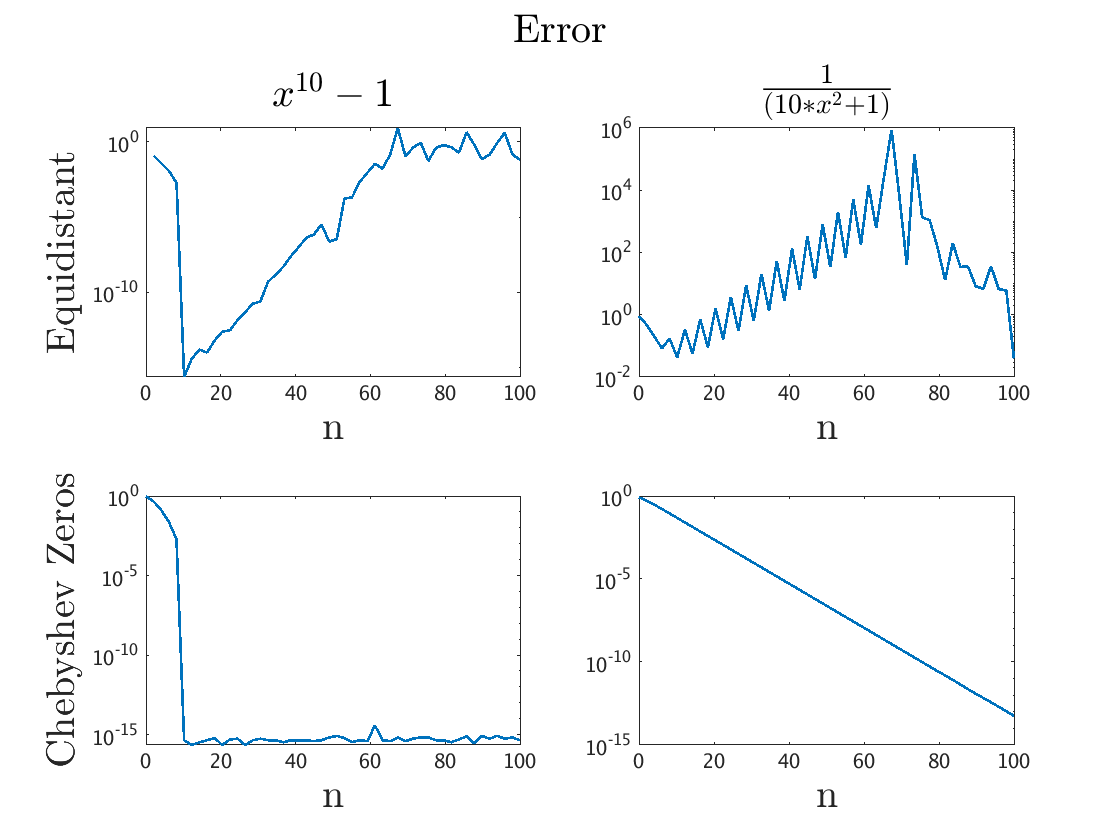

figure
subplot(2,2,1)
semilogy(linspace(0,100,50),max_error_1, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
ylabel('Equidistant','Interpreter','latex', 'FontSize', 30)
title('$x^{10}-1$','Interpreter','latex', 'FontSize', 30)

subplot(2,2,2)
semilogy(linspace(0,100,50),max_error_2, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
title('$\frac{1}{(10*x^2+1)}$', 'Interpreter','latex', 'FontSize', 30)

subplot(2,2,3)
semilogy(linspace(0,100,50),max_error_3, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
ylabel('Chebyshev Zeros','Interpreter','latex', 'FontSize', 30)

subplot(2,2,4)
semilogy(linspace(0,100,50),max_error_4, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
sgtitle('Error', 'Interpreter','latex', 'FontSize', 30)

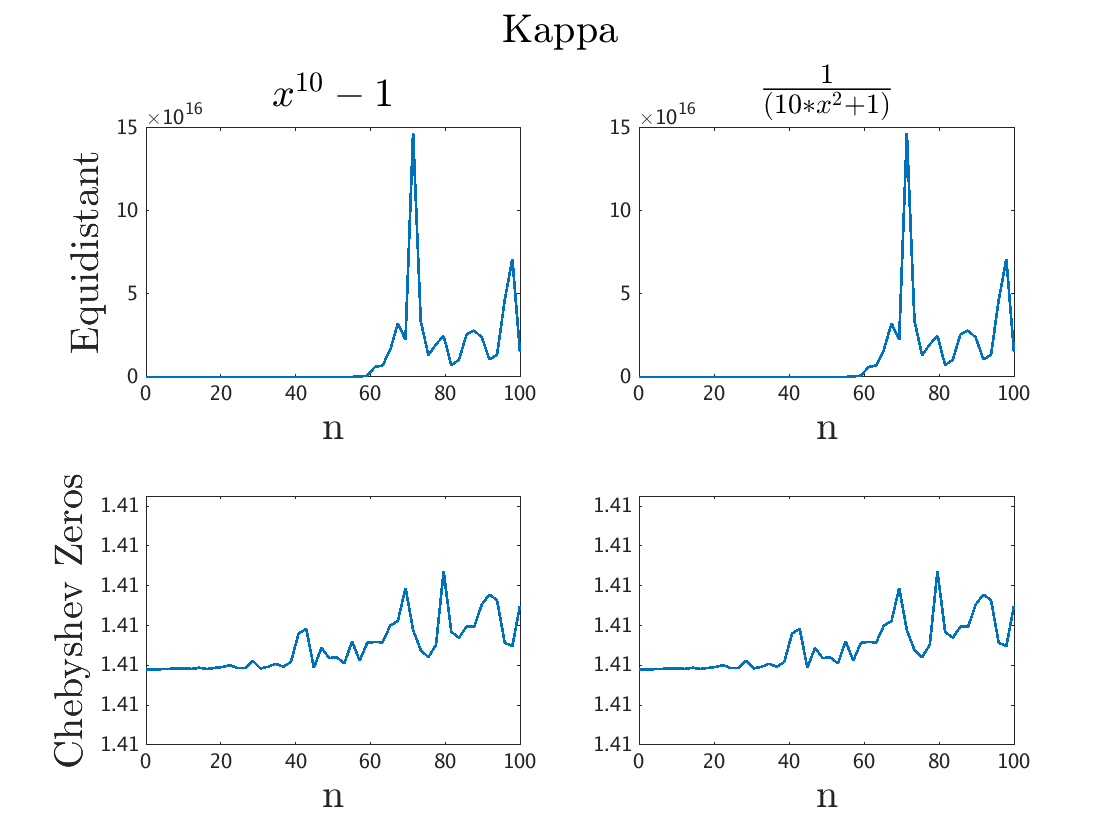

figure
subplot(2,2,1)
plot(linspace(0,100,50), kappa_1, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
ylabel('Equidistant','Interpreter','latex', 'FontSize', 30)
title('$x^{10}-1$','Interpreter','latex', 'FontSize', 30)

subplot(2,2,2)
plot(linspace(0,100,50), kappa_2, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
title('$\frac{1}{(10*x^2+1)}$', 'Interpreter','latex', 'FontSize', 30)

subplot(2,2,3)
plot(linspace(0,100,50), kappa_3, 'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
ytickformat('%.2f')
ylabel('Chebyshev Zeros','Interpreter','latex', 'FontSize', 30)

subplot(2,2,4)
plot(linspace(0,100,50), kappa_4,  'LineWidth', 2)
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
ytickformat('%.2f')
sgtitle('Kappa', 'Interpreter','latex', 'FontSize', 30)

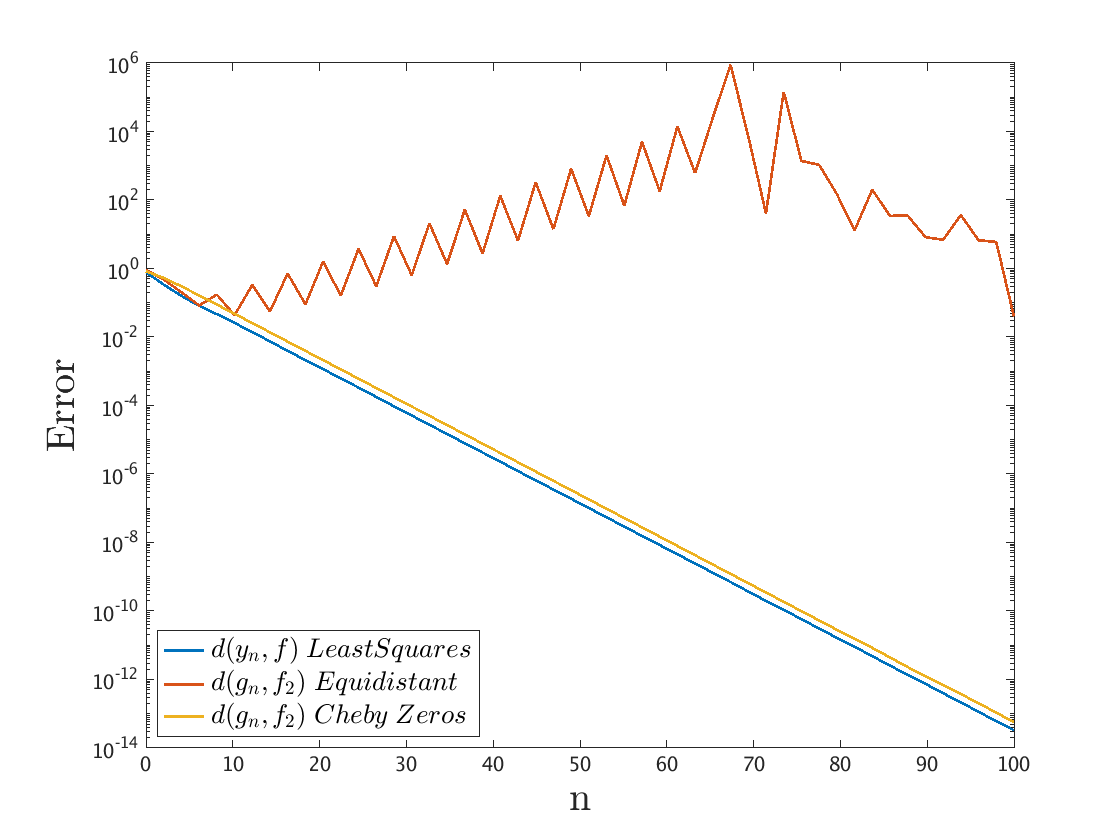

figure
semilogy(linspace(0,100,50), d, 'LineWidth', 2)
hold on
semilogy(linspace(0,100,50), max_error_2, 'LineWidth', 2)   
semilogy(linspace(0,100,50),max_error_4, 'LineWidth', 2)
hold off
xlabel('n', 'Interpreter','latex', 'FontSize', 30)
ylabel('Error','Interpreter','latex', 'FontSize', 30)
legend({'$d(y_{n},f) \; Least Squares$', '$d(g_{n}, f_{2}) \;Equidistant$', '$d(g_{n}, f_{2}) \;Cheby \;Zeros$'}, 'Interpreter','latex', 'Location', 'southwest', 'FontSize', 20)

% title('Error', 'Interpreter','latex', 'FontSize', 30)